% AAE 666 HW9 PROBLEM 4 MATLAB CODE 
% TOMOKI KOIKE

% Houskeeping commands 
clear all; close all; clc;

% Compute omega and a values for the describing function numerically 
h = 1  % time delay constant

h = 1

tol = 1e-6;  % tolerance
for omega = 0.1:0.0000001:10
    delta = abs(tan(omega) + omega);
    if delta < tol 
        break 
    end
end
format long;
disp(omega);

   2.028757700000000



format;

% Compute a 
syms a
assume(a, {'positive', 'real'});
eqn = 8*cos(omega*h) - 8*omega*sin(omega*h) + pi*a*omega^2 + pi*a == 0;
a = solve(eqn, a);
format long ;
disp(a);

$$1.1259$$

format
a = double(a);

% Period 
T = 2*pi / omega

T = 3.0971

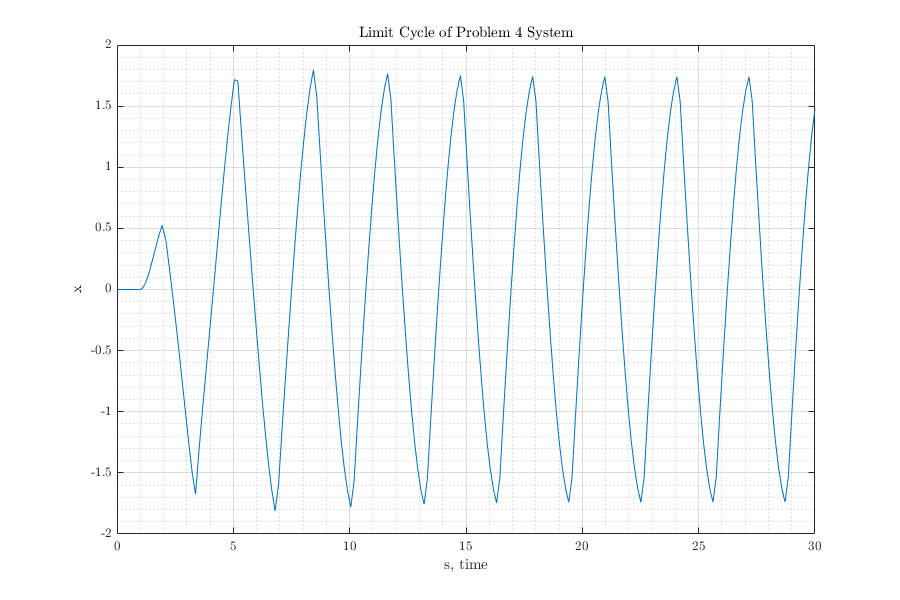

% Simulate 
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');
out = sim('p4_signum.slx');

t = out.tout;
x = out.simout.signals.values;

fig = figure("Renderer","painters", "Position",[60 60 900 600]);
    plot(t, x);
    grid on; grid minor; box on;
    xlabel('s, time')
    ylabel('x')
    title('Limit Cycle of Problem 4 System')
saveas(fig, 'p4_result.png');